# Example D from Lecture L3b:  Bézier curve

Let's have some control points first, again: 

close all; clear all; clc

We set up some control points (as row vectors): 

%    x  y
p = [1, 1; 
     2, 2; 
     3, 2; 
     3, 3]

p =      1     1
     2     2
     3     2
     3     3


%
% Alternatively: 
% p = [0, 0;  3, 0;  3, 2;  2, 2;  2, 3;  3, 3;  4, 4;  5, 3;  6, 2;  6, 1;  6, 0]
%

Let's have a look at them:

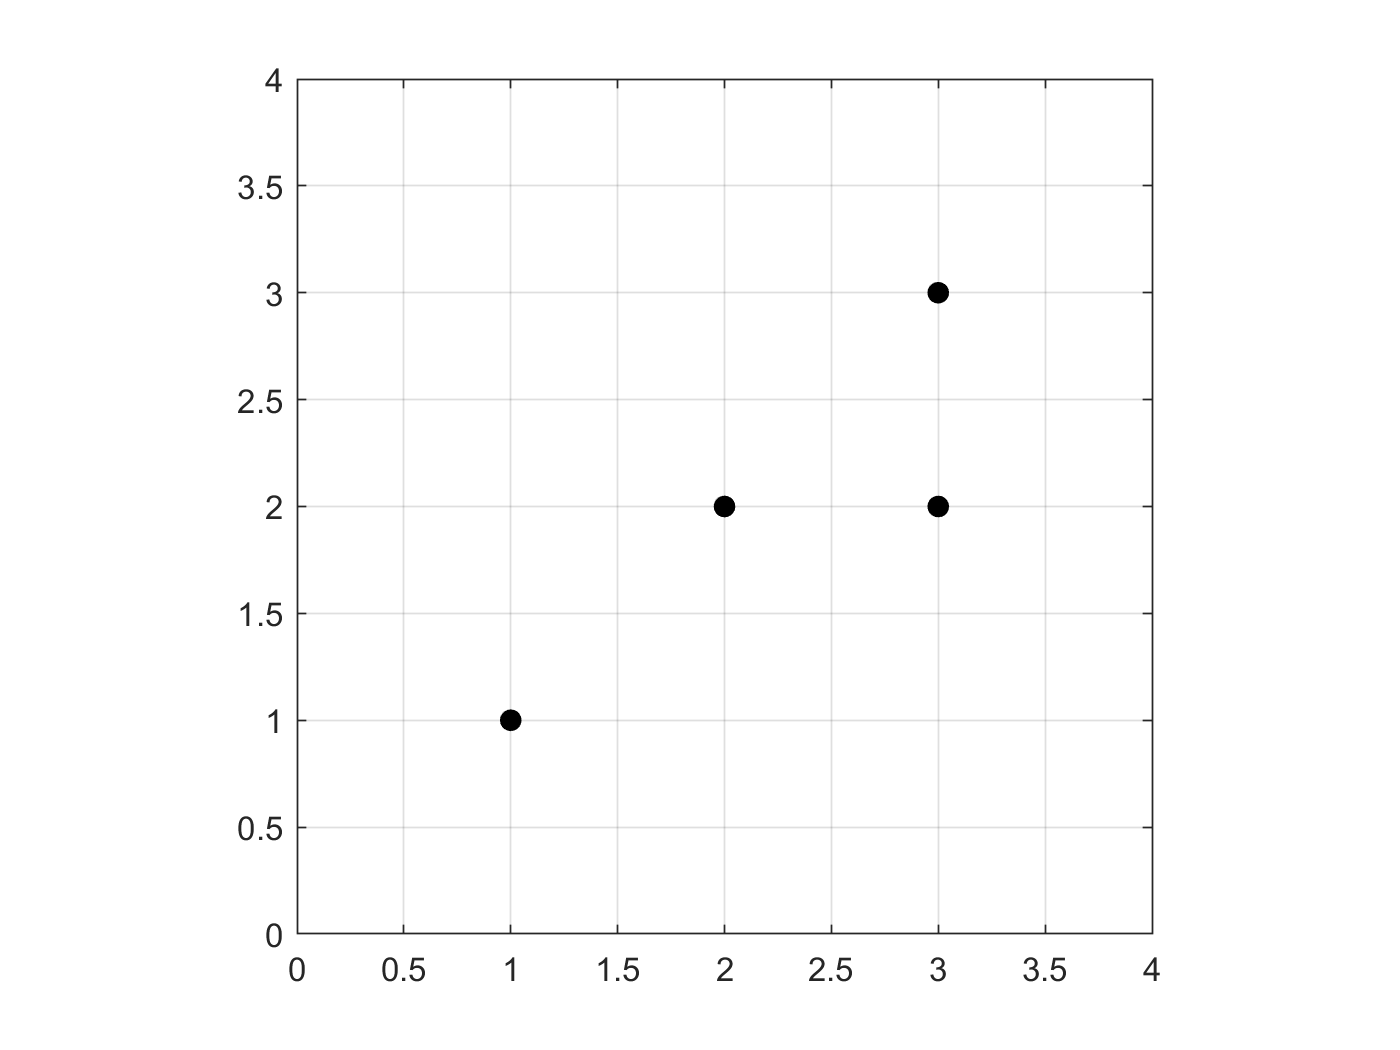

figure;
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)

To get the coefficients of the Hermite splines, we also need the Hermit matrix, $\mathbf{M}_\textit{Bez}$: 

M_Bez = [ -1  3 -3  1; ...
           3 -6  3  0; ...
          -3  3  0  0; ...
           1  0  0  0] % the Bezier matrix

M_Bez =     -1     3    -3     1
     3    -6     3     0
    -3     3     0     0
     1     0     0     0


With this, we are ready to compute and visualize the interpolating Hermite spline curve:

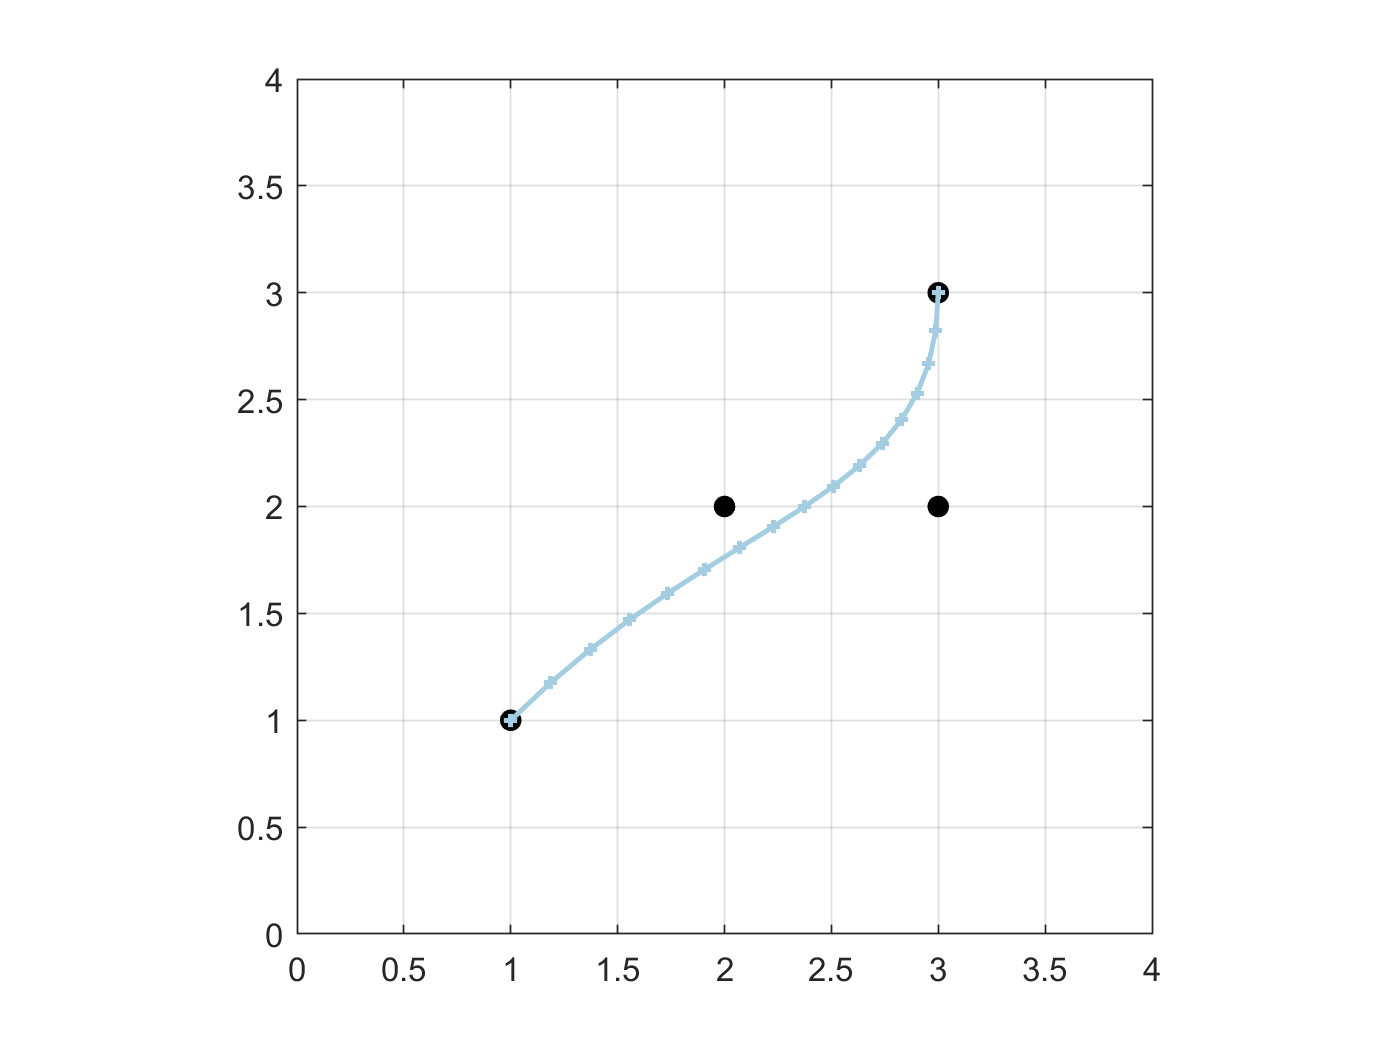

figure;
cm = [166,206,227; 31,120,180; 178,223,138; 51,160,44; 251,154,153; 227,26,28; 253,191,111; 255,127,0]/256; 
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)
FineLine = linspace(0, 1, 17).'; 
q = [power(FineLine,3) power(FineLine,2) FineLine ones(length(FineLine),1)] * M_Bez * p; 
plot(q(:,1), q(:,2), '+', 'Color', cm(1,:), 'LineWidth', 1.5, 'MarkerSize', 4)
plot(q(:,1), q(:,2),      'Color', cm(1,:), 'LineWidth', 1.5)

Let's get some impression of how the spline curve responds to varying one of the control points:

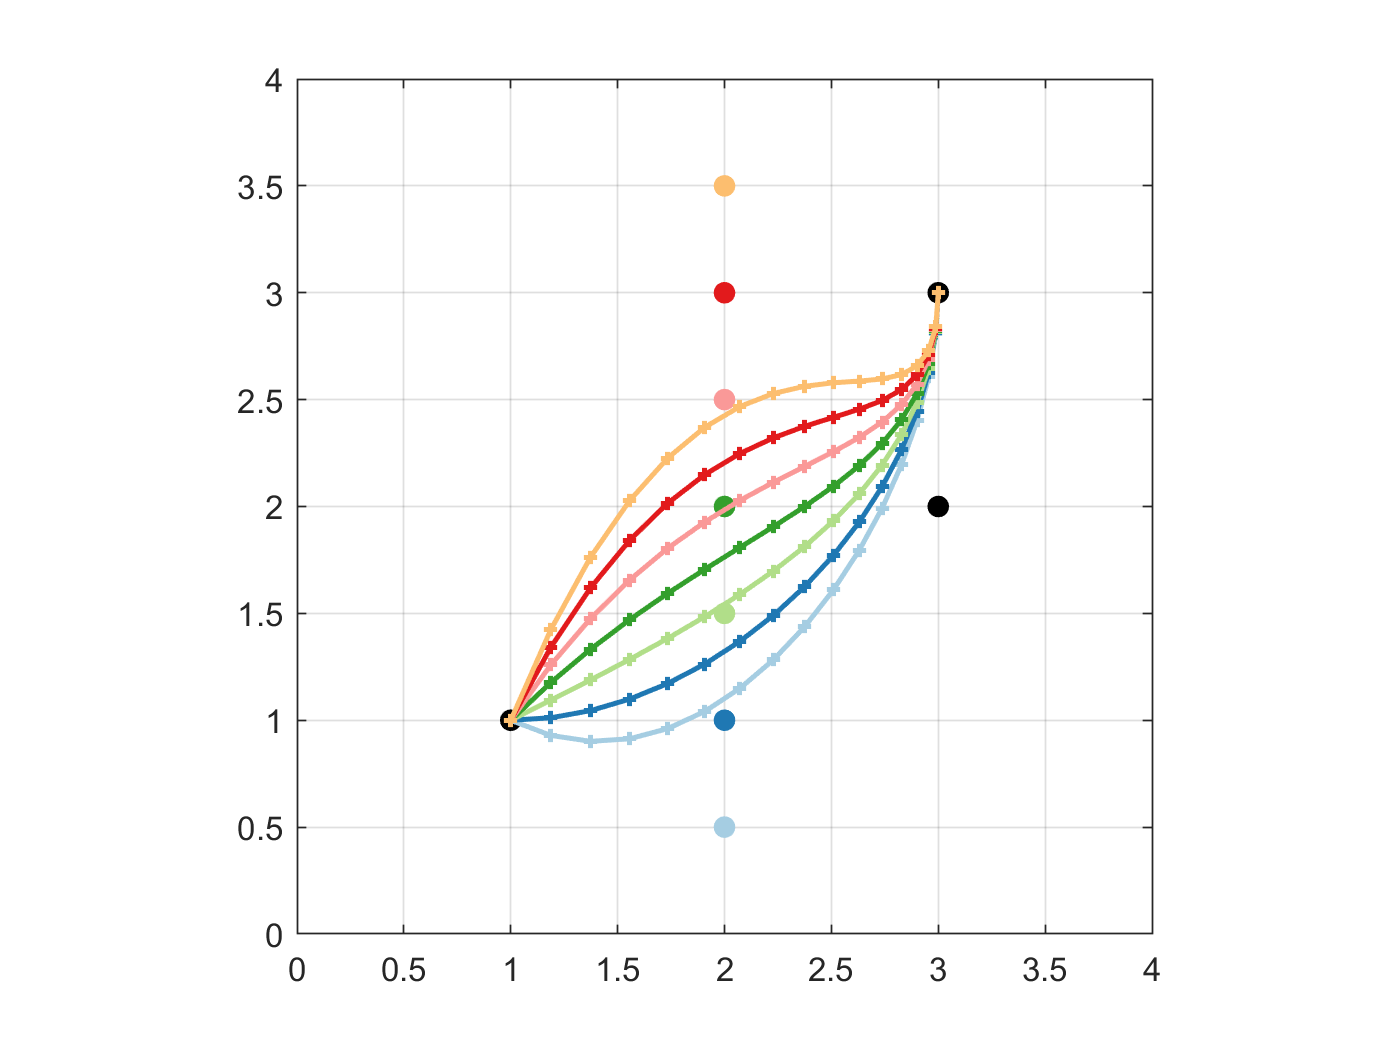

ys = (0.5:0.5:3.5).'; % let's vary the y-component of the chosen point
ts = [2*ones(length(ys),1) ys]; 
figure;
plot (p(:,1), p(:,2), 'ko', 'MarkerFaceColor', 'k'), grid on, axis equal, hold on
axis([min(p(:,1))-1 max(p(:,1))+1 min(p(:,2))-1 max(p(:,2))+1])
xticks(min(p(:,1))-1:0.5:max(p(:,1))+1)
yticks(min(p(:,2))-1:0.5:max(p(:,2))+1)
for v = 1:length(ys)
    p(2,:) = ts(v,:); % set in the chosen point
    plot (p(2,1), p(2,2), 'o', 'Color', cm(v,:), 'MarkerFaceColor', cm(v,:))
    q = [power(FineLine,3) power(FineLine,2) FineLine ones(length(FineLine),1)] * M_Bez * p; 
    plot(q(:,1), q(:,2), '+', 'Color', cm(v,:), 'LineWidth', 1.5, 'MarkerSize', 4)
    plot(q(:,1), q(:,2),      'Color', cm(v,:), 'LineWidth', 1.5)
end

EOF.